%This code reproduces Fig2 from the second rebuttal submitted to Nature2020
%paper (Nienhuis et al., 2020). It needs v1 dataset provided by Jaap Nienhuis

v1 = load ('V1\GlobalDeltaData_v1.mat');%provided by Jaap Nienhuis
%v11 = load ('V1.1\GlobalDeltaData.mat');
v2 = load ('V2\GlobalDeltaData.mat') %from https://github.com/jhnienhuis/GlobalDeltaChange

v2 = struct with fields:
          BasinArea: [10848×1 double]
            BasinID: [10848×1 double]
           BasinID2: [10848×1 int64]
      BasinID_ATLAS: [10848×1 int64]
       ChannelSlope: [10848×1 double]
          Continent: [10848×1 double]
     Discharge_dist: [10848×1 double]
    Discharge_prist: [10848×1 double]
     Discharge_tide: [10848×1 double]
                 Hs: [10848×1 double]
           MouthLat: [10848×1 double]
           MouthLon: [10848×1 double]
        QRiver_dist: [10848×1 double]
       QRiver_prist: [10848×1 double]
              QTide: [10848×1 double]
              QWave: [10848×1 double]
             Region: [10848×1 int32]
         Region_str: {1×20 cell}
      RiverID_ATLAS: [1×10848 int64]
           TidalAmp: [10848×1 double]
                 Tp: [10848×1 double]
        channel_len: [10848×30 double]
    channel_len_lat: [10848×30 double]
    channel_len_lon: [10848×30 double]
      channel_slope: [10848×1 double]
         delta_name: [10848×1 s

v2.ee = load('V2\land_area_change\GlobalDeltaData_AreaChange.mat');
load 'V1/BasinID2';
BasinID2 = double(BasinID2);

%Max 100
Max_deltas100 = readtable('EE_Max100Big_polys_change.csv');

Max_deltas100_orig = readtable('GlobalDeltaMax100ID.csv');
[~,DeltaID_Max100] = ismember(Max_deltas100.ID, BasinID2);
[~,DeltaID_Max100_orig] = ismember(Max_deltas100_orig.BasinID2, BasinID2);
Max_deltas100_change = Max_deltas100.change2/28;

%logical without Yellow

NoYellow = (zeros(1, 10848)+1)';
NoYellow(6302) = 0;
NoYellow = logical(NoYellow);

%logical without max 100
NoMax100 = (zeros(1, 10848)+1)';
NoMax100(DeltaID_Max100_orig) = 0;
NoMax100= logical(NoMax100);

Max100 = ~NoMax100;
Max100_noYellow = Max100;
Max100_noYellow(6302) = 0;


%get zoom log
Qdist_Qprist = v1.QRiver_dist-v1.QRiver_prist;
Diff_zoom_log = Qdist_Qprist > -250 & Qdist_Qprist < 250 & v1.ee.net_aqua >-0.25 & v1.ee.net_aqua < 0.25;

%get large deltas log
NoYellow_large = Qdist_Qprist > -250 & Qdist_Qprist < 250 & v1.ee.net_aqua >-0.25 & v1.ee.net_aqua < 0.25;

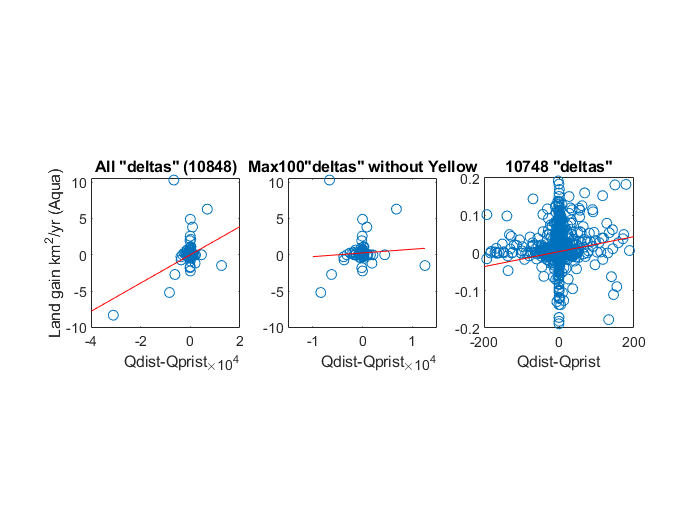

clf

ax1 = subplot(1,3,1);
scatter(v1.QRiver_dist-v1.QRiver_prist, v1.ee.net_aqua)

h1 = lsline(ax1);
h1(1).Color = 'r'; % regression only cut data bins
%h1(2).LineWidth = 1.5;

xlim([-40000 20000])
ylim([-10 10.5])

xlabel 'Qdist-Qprist'
ylabel 'Land gain km^2/yr (Aqua)'
axis square
box on
title 'All "deltas" (10848)'


ax2 = subplot(1,3,2);
scatter(v1.QRiver_dist(Max100_noYellow)-v1.QRiver_prist(Max100_noYellow), v1.ee.net_aqua(Max100_noYellow))

h1 = lsline(ax2);
h1(1).Color = 'r'; % regression only cut data bins
%h1(2).LineWidth = 1.5;

xlim([-15000 15000])
ylim([-10 10.5])
xlabel 'Qdist-Qprist'
%ylabel 'Land gain km^2/yr (Aqua)'
title 'Max100"deltas" without Yellow'
axis square
box on


ax3 = subplot(1,3,3);
scatter(v1.QRiver_dist(NoMax100)-v1.QRiver_prist(NoMax100), v1.ee.net_aqua(NoMax100))

h1 = lsline(ax3);
h1(1).Color = 'r'; 
%h1(2).LineWidth = 1.5;

xlim([-200 200])
ylim([-0.2 0.2])
xlabel 'Qdist-Qprist'
%ylabel 'Land gain km^2/yr (Aqua)'
axis square
box on
title '10748 "deltas"'


sum(NoYellow)

ans = 10847

sum(Diff_zoom_log)

ans = 10745

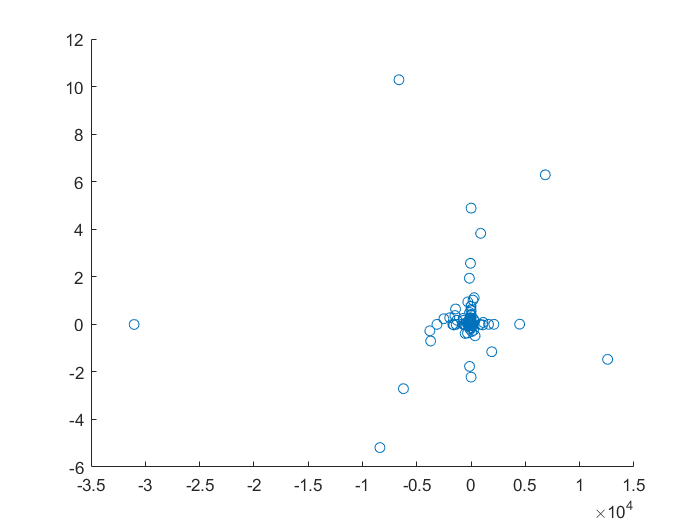

%scatter with Yellow corrected
Yellow_corr = v1.ee.net_aqua;
Yellow_corr(6302) = Max_deltas100_change(16);
Yellow_corr = Yellow_corr(Max100);

clf
scatter(v1.QRiver_dist(Max100)-v1.QRiver_prist(Max100), Yellow_corr)

regression_QdistQprist_diff = fitlm(v1.QRiver_dist-v1.QRiver_prist, v1.ee.net_aqua)

regression_QdistQprist_diff = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate         SE        tStat       pValue  
                   _________    __________    ______    __________

    (Intercept)    0.0058954     0.0015431    3.8205    0.00013393
    x1             0.0001944    4.2502e-06    45.739             0


Number of observations: 10848, Error degrees of freedom: 10846
Root Mean Squared Error: 0.161
R-squared: 0.162,  Adjusted R-Squared: 0.162
F-statistic vs. constant model: 2.09e+03, p-value = 0

regression_QdistQprist_NoYellow = fitlm(v1.QRiver_dist(NoYellow)-v1.QRiver_prist(NoYellow), v1.ee.net_aqua(NoYellow))

regression_QdistQprist_NoYellow = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                    Estimate         SE        tStat       pValue  
                   __________    __________    ______    __________

    (Intercept)     0.0058323     0.0014986    3.8918    0.00010011
    x1             4.2825e-05    7.2215e-06    5.9302    3.1174e-09


Number of observations: 10847, Error degrees of freedom: 10845
Root Mean Squared Error: 0.156
R-squared: 0.00323,  Adjusted R-Squared: 0.00314
F-statistic vs. constant model: 35.2, p-value = 3.12e-09

regression_QdistQprist_Yellow_corr = fitlm (v1.QRiver_dist(Max100)-v1.QRiver_prist(Max100), Yellow_corr)

regression_QdistQprist_Yellow_corr = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                    Estimate         SE         tStat     pValue 
                   __________    __________    _______    _______

    (Intercept)       0.25646       0.15847     1.6183    0.10881
    x1             2.2201e-05    4.2025e-05    0.52828     0.5985


Number of observations: 100, Error degrees of freedom: 98
Root Mean Squared Error: 1.57
R-squared: 0.00284,  Adjusted R-Squared: -0.00734
F-statistic vs. constant model: 0.279, p-value = 0.598

regression_QdistQprist_Max100NoYellow = fitlm(v1.QRiver_dist(Max100_noYellow)-v1.QRiver_prist(Max100_noYellow), v1.ee.net_aqua(Max100_noYellow))

regression_QdistQprist_Max100NoYellow = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                    Estimate         SE         tStat     pValue 
                   __________    __________    _______    _______

    (Intercept)       0.25797       0.15913     1.6211    0.10824
    x1             5.1052e-05    7.3893e-05    0.69089    0.49128


Number of observations: 99, Error degrees of freedom: 97
Root Mean Squared Error: 1.58
R-squared: 0.0049,  Adjusted R-Squared: -0.00536
F-statistic vs. constant model: 0.477, p-value = 0.491

regression_QdistQprist_NoMax100 = fitlm(v1.QRiver_dist(NoMax100)-v1.QRiver_prist(NoMax100), v1.ee.net_aqua(NoMax100))

regression_QdistQprist_NoMax100 = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                    Estimate         SE        tStat       pValue  
                   __________    __________    ______    __________

    (Intercept)     0.0035194     0.0003794    9.2764    2.0891e-20
    x1             0.00020002    1.3917e-05    14.372    2.0891e-46


Number of observations: 10748, Error degrees of freedom: 10746
Root Mean Squared Error: 0.0393
R-squared: 0.0189,  Adjusted R-Squared: 0.0188
F-statistic vs. constant model: 207, p-value = 2.09e-46

%find yellow
%find(v1.ee.net_aqua == min(v1.ee.net_aqua)); % Find the outlier mouth
%v1.MouthLat(6302)% get lat

ans = 37.7708

ans = 119.1750

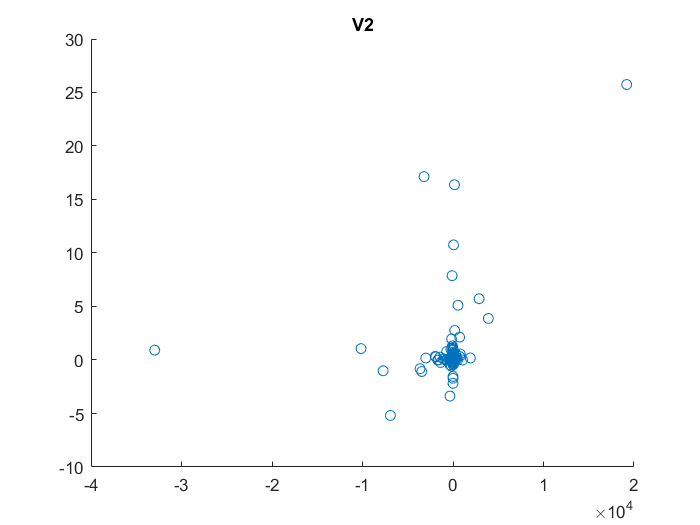

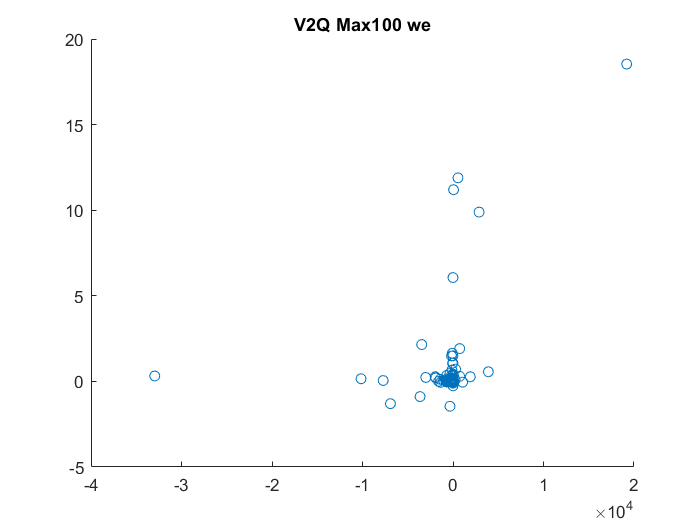

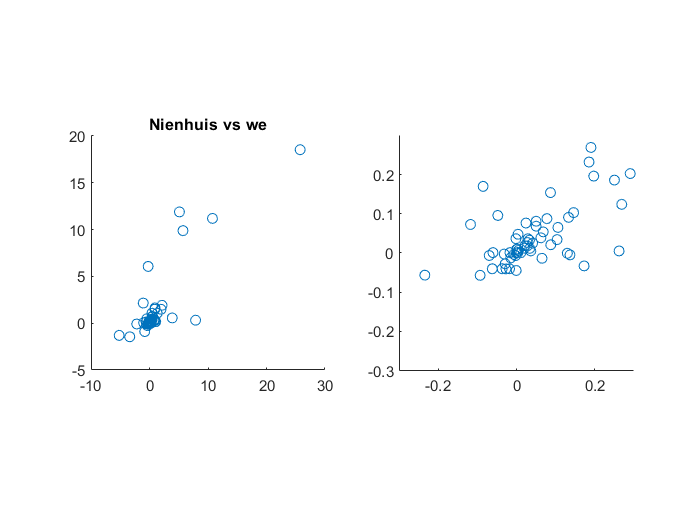

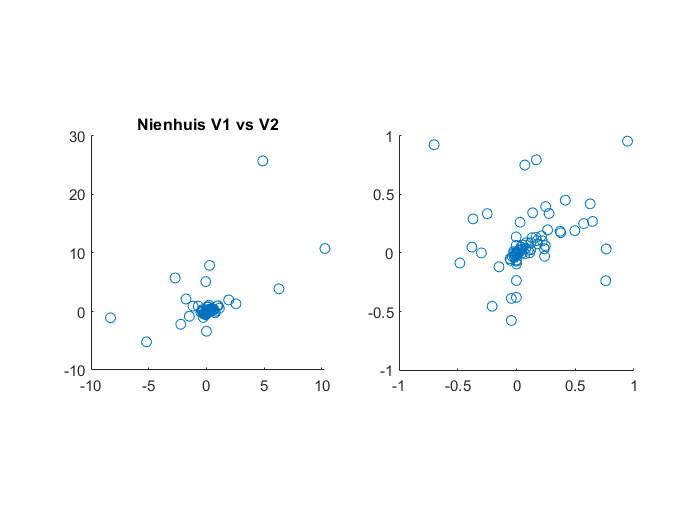

ans = 4717

regression_QdistQprist_V2 = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                    Estimate         SE        tStat       pValue  
                   __________    __________    ______    __________

    (Intercept)      0.013965     0.0034858    4.0063    6.2082e-05
    x1             0.00027637    8.6377e-06    31.995    9.918e-215


Number of observations: 10848, Error degrees of freedom: 10846
Root Mean Squared Error: 0.363
R-squared: 0.0862,  Adjusted R-Squared: 0.0862
F-statistic vs. constant model: 1.02e+03, p-value = 9.92e-215

regression_QdistQprist_V2Max100 = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate         SE        tStat       pValue  
                   _________    __________    ______    __________

    (Intercept)      0.84363       0.29705      2.84     0.0055536
    x1             0.0003345    6.8858e-05    4.8578    4.8518e-06


Number of observations: 94, Error degrees of freedom: 92
Root Mean Squared Error: 2.85
R-squared: 0.204,  Adjusted R-Squared: 0.195
F-statistic vs. constant model: 23.6, p-value = 4.85e-06

regression_QdistQprist_Max100 = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                    Estimate         SE        tStat       pValue  
                   __________    __________    ______    __________

    (Intercept)       0.91679       0.26762    3.4257    0.00091816
    x1             0.00024983    6.2035e-05    4.0272    0.00011597


Number of observations: 94, Error degrees of freedom: 92
Root Mean Squared Error: 2.57
R-squared: 0.15,  Adjusted R-Squared: 0.141
F-statistic vs. constant model: 16.2, p-value = 0.000116

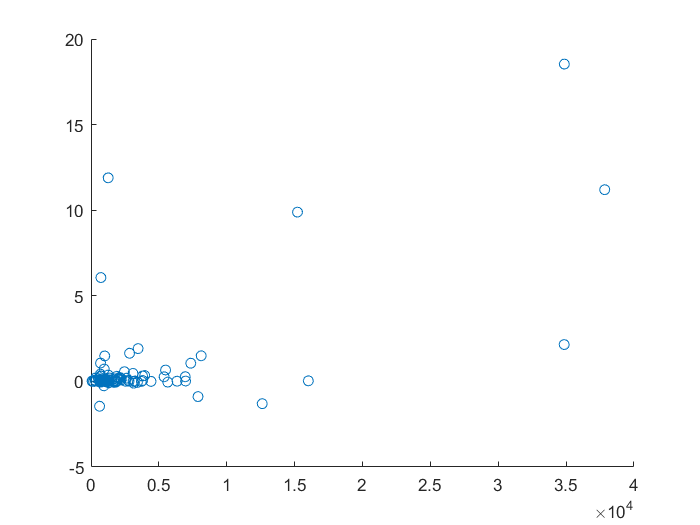

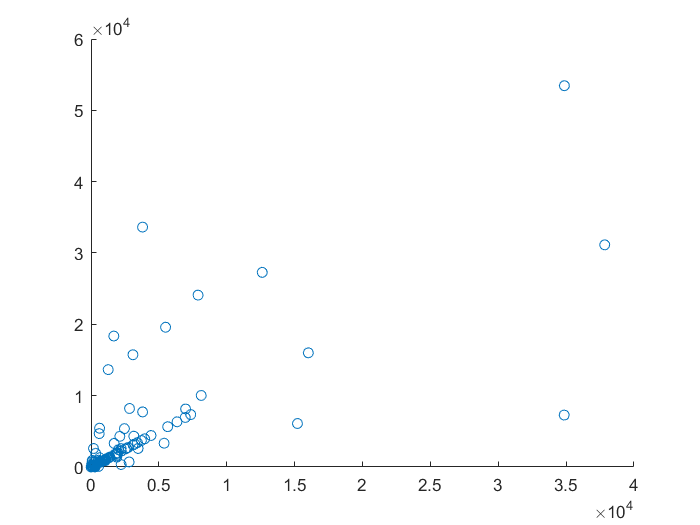

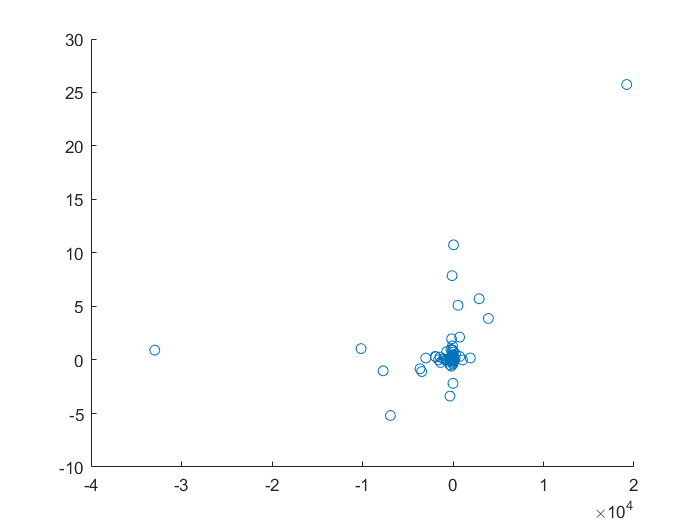

%v1.MouthLon(6302)%get lon